Nota: se podría tomar t0 = 0 para todos los problemas.

## MODELOS LINEALES

## Modelo 1

Modelo de crecimiento lineal.

Supongamos que hacemos una imposición mensual de una cantidad en un banco.


$$\begin{array}{l}
\frac{\textrm{dM}}{\textrm{dt}}=k\\
\textrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$



$$\begin{array}{l}
k\;\;\;\;\;\;\;\;=\mathrm{cantidad}\;\mathrm{depositada}\;\mathrm{mensualmente}\\
M\left(t\right)=\mathrm{cantidad}\;\mathrm{de}\;\mathrm{dinero}\;\mathrm{en}\;\mathrm{la}\;\mathrm{cuenta}\;\mathrm{en}\;\mathrm{un}\;\mathrm{instante}\;t
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms M(t) k M0 t0

edo = diff(M, t, 1) == k;
cond = [M(t0)==M0];

M(t) = dsolve(edo, cond);
M(t) = collect(M(t), k)     % para sacar factor comun

$$M(t) = \left(t-t_{0}\right)\,k+M_{0}$$

#### 2. Sustitución de valores iniciales y constante k

k_values =  [2, 3, -2];
ic_values = [0 1; 0 8; 0 1];
t_values = 0:5:10;
[m, n] = size(k_values);

#### 3. Gráfica para cada caso

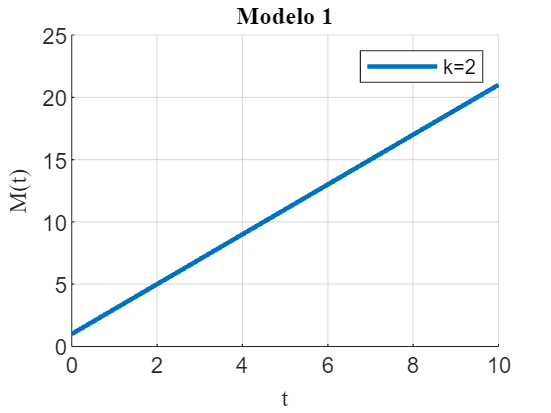

figure;
hold on;

for i = 1:1%n
    M_subs = subs(M, k, k_values(i));
    M_subs = subs(M_subs, [t0, M0], [ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['k=' num2str(k_values(i))]);
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Modelo 1','FontName','latex');
legend('show');
grid on;
hold off;

Estamos ante un modelo de crecimiento lineal. Para:

$k>0\;$crecimiento

$k<0\;$decrecimiento

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$0=k\;$$


La estabilidad no se alcanza para ningún valor de k distinto de 0 ni para ninguna condición inicial, ya que es un modelo lineal, que crece o decrece de manera constante.

No es muy realista porque supone que solo hacemos imposiciones.

## Modelo 2

Modelo de crecimiento lineal.

En este modelo también se saca dinero. En concreto hacemos un gasto $s$ por mes.


$$\begin{array}{l}
\frac{\textrm{dM}}{\textrm{dt}}=k-s\\
\textrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$



$$\begin{array}{l}
k\;\;\;\;\;\;\;\;=\mathrm{cantidad}\;\mathrm{depositada}\;\mathrm{mensualmente}\\
M\left(t\right)=\mathrm{cantidad}\;\mathrm{de}\;\mathrm{dinero}\;\mathrm{en}\;\mathrm{la}\;\mathrm{cuenta}\;\mathrm{en}\;\mathrm{un}\;\mathrm{instante}\;t\\
s\;\;\;\;\;\;\;=\mathrm{cantidad}\;\mathrm{de}\;\mathrm{gasto}\;\mathrm{mensual}
\end{array}$$


#### 1. Sustitución de valores iniciales y constante k

clc, clear


syms M(t) k M0 t0 s 

edo = diff(M, t, 1) == k - s;

cond = [M(t0)==M0];

M(t) = dsolve(edo, cond);
M(t) = collect(M(t), [k, s])     % para sacar factor comun

$$M(t) = \left(t-t_{0}\right)\,k+\left(t_{0}-t\right)\,s+M_{0}$$

#### 2. Sustitución de valores iniciales y constante k

k_values =  [2, 3, -2];
s_values = [4, 1, -2];
ic_values = [0 1; 0 8; 0 5];
t_values = 0:5:10;
[m, n] = size(k_values);

#### 3. Gráfica para cada caso

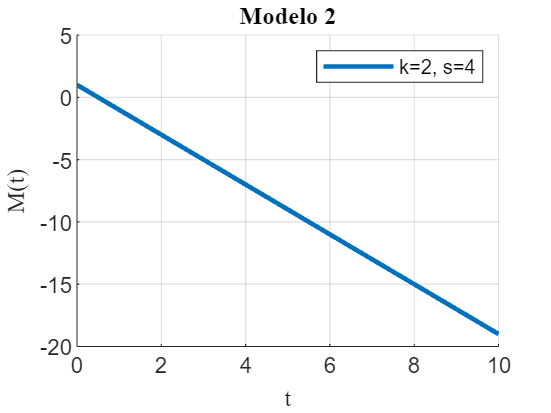

figure;
hold on;

for i = 1:1%n
    M_subs = subs(M, [k s], [k_values(i) s_values(i)]);
    M_subs = subs(M_subs, [t0, M0], [ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['k=' num2str(k_values(i)) ', s=' num2str(s_values(i))]);
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Modelo 2','FontName','latex');
legend('show');
grid on;
hold off;

Estamos ante un modelo de crecimiento lineal. Para:

$k>s$ crecimiento (ahorramos más que gastamos)

$k<s$ decrecimiento (gastamos más que ahorramos)

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=k-s\\
k=s
\end{array}$$


syms M k s
eq = k - s == 0;
k = solve(eq,k)

$$k = s$$

La estabilidad solo se alcanza si $k=s$ ya que, entonces gastamos lo mismo que ahorramos.

## MODELOS EXPONENCIALES

## Modelo 3

Modelo de crecimiento exponencial.

En lugar de gastar una cantidad fija, para este modelo gastamos una cantidad proporcional a lo que tenemos, es decir, tengo más $\to$ gasto más; tengo menos $\to$ gasto menos.

Por tanto: $s\proptoM\to s=r\cdot M$

Y el modelo sería: 


$$\begin{array}{l}
\frac{\mathrm{dM}}{\mathrm{dt}}=k-r\cdot M\\
\mathrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$



$$\begin{array}{l}
k\;\;\;\;\;\;\;\;=\textrm{cantidad}\;\textrm{depositada}\;\textrm{mensualmente}\\
M\left(t\right)=\textrm{cantidad}\;\textrm{de}\;\textrm{dinero}\;\textrm{en}\;\textrm{la}\;\textrm{cuenta}\;\textrm{en}\;\textrm{un}\;\textrm{instante}\;t\\
s\;\;\;\;\;\;\;=\textrm{cantidad}\;\textrm{de}\;\textrm{gasto}\;\textrm{mensual}\\
r\;\;\;\;\;\;\;=\textrm{proporción}\;\textrm{de}\;\textrm{gasto}
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms M(t) k M0 t0 r

edo = diff(M, t, 1) == k - r*M;
cond = [M(t0)==M0];

M(t) = dsolve(edo, cond)

$$M(t) = \frac{k-{\mathrm{e}}^{-r\,t}\,\left(k\,{\mathrm{e}}^{r\,t_{0}}-M_{0}\,r\,{\mathrm{e}}^{r\,t_{0}}\right)}{r}$$

M(t) = collect(M(t), [k,r,t])     % para sacar factor comun

$$M(t) = \frac{\left(1-{\mathrm{e}}^{r\,t_{0}}\,{\mathrm{e}}^{-r\,t}\right)\,k+\left(M_{0}\,{\mathrm{e}}^{r\,t_{0}}\,{\mathrm{e}}^{-r\,t}\right)\,r}{r}$$

#### 2. Sustitución de valores iniciales y constante k

k_values =  [2, 2, 2];
r_values = [0.4, 0.1, 0.8];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

#### 3. Gráfica para cada caso 

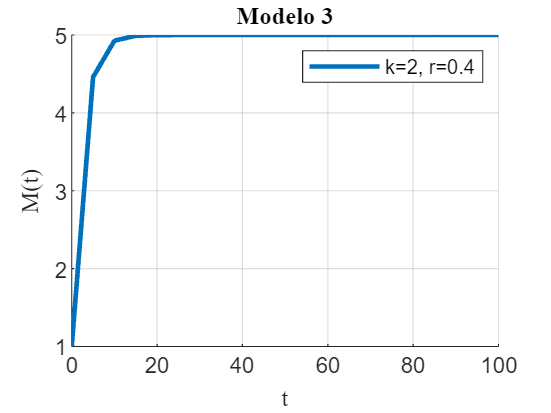

figure;
hold on;
for i = 1:1%n
    M_subs = subs(M, [k r t0 M0], [k_values(i) r_values(i), ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['k=' num2str(k_values(i)) ', r=' num2str(r_values(i))]); 
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Modelo 3','FontName','latex');
legend('show');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra (para r = 0.8, los valores de M(t) son menores).

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=k-r\cdot M\\
M=\frac{k}{r}
\end{array}$$


syms M_stable k r
eq = k - r*M_stable== 0;
M_stable = solve(eq,M_stable)

$$M\_stable = \frac{k}{r}$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=\frac{k}{r}$. Por ejemplo:$\textrm{Para}\;\;k=2;r=0\ldotp 1\;\left(\textrm{función}\;\textrm{naranja}\right)\;\to M=\;\frac{k}{r}\;=\;\frac{2}{0\ldotp 1}\;=\;20$; se estabiliza en 20. 

M_stable = subs(M_stable, r, 0.1)

$$M\_stable = 10\,k$$

M_stable = subs(M_stable, k, 2)

$$M\_stable = 20$$

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Nombre del modelo

model_name = "modelo3";

Condiciones iniciales y constantes del modelo:

k_values =  [2, 2, 2];
r_values = [-0.4, -0.1, -0.8];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
M1 = signals{1}.Values.Data

M1 =     1.6000    1.9000    1.2000
    1.5337    1.8800    1.1026
    1.3603    1.8244    0.8674
    1.2065    1.7705    0.6823
    1.0700    1.7182    0.5367
    0.9490    1.6674    0.4222
    0.8417    1.6181    0.3321
    0.7465    1.5703    0.2612
    0.6621    1.5239    0.2055
    0.5873    1.4789    0.1617


M = signals{2}.Values.Data

M =     1.0000    1.0000    1.0000
    1.1657    1.1999    1.1217
    1.5993    1.7555    1.4158
    1.9838    2.2947    1.6471
    2.3249    2.8180    1.8291
    2.6274    3.3258    1.9723
    2.8957    3.8186    2.0849
    3.1336    4.2968    2.1734
    3.3447    4.7609    2.2431
    3.5319    5.2113    2.2979


signal_time = signals{1}.Values.Time;

#### Gráfica 1

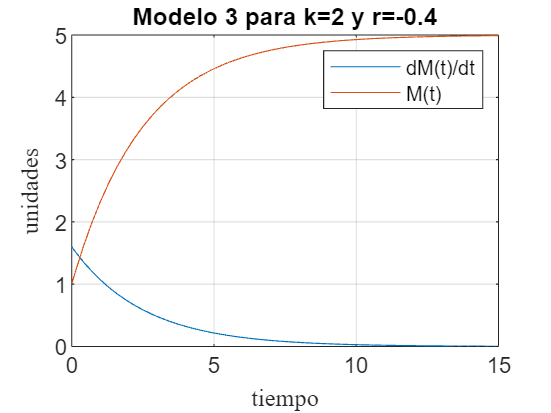

[m, n] = size(M1);
for i =1:1%n
    figure
    plot(signal_time, M1(:,i))
    hold on
    plot(signal_time, M(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 3 para k=' num2str(k_values(i)) ' y r=' num2str(r_values(i))]);
    legend('dM(t)/dt','M(t)');
    hold off
end 

#### Gráfica 2

[m, n] = size(M1);
figure
for i =1:1%n
    plot(M(:,i), M1(:,i), 'DisplayName', ['k=' num2str(k_values(i)) ', r=' num2str(r_values(i))])
    grid on
    xlabel("M(t)","FontName","latex");
    ylabel("dM(t)/dt","FontName","latex");
    title('Modelo 3 para gráfica M, dM/dt');
    hold on
end 
legend('show')

## Modelo 4

Modelo de decrecimiento exponencial.

Supongamos un $k=0$ es decir, dejamos de ganar.


$$\begin{array}{l}
\frac{\mathrm{dM}}{\mathrm{dt}}=-r\cdot M\\
\mathrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms M(t) M0 t0 r

edo = diff(M, t, 1) == - r*M;
cond = [M(t0)==M0];

M(t) = dsolve(edo, cond)

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t_{0}}\,{\mathrm{e}}^{-r\,t}$$

M(t) = collect(M(t), [r,t])     % para sacar factor comun

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t_{0}}\,{\mathrm{e}}^{-r\,t}$$

#### Cálculo de la vida media

Este modelo está asociado al problema de **vida media**, que es el tiempo que transcurre para que la cantidad de la magnitud física medida se reduzca a la mitad.


$$M\left(t\right)=\frac{M_o }{2}$$


vida_media = solve(M == M0/2, t)

$$vida\_media = -\frac{\log\left(\frac{{\mathrm{e}}^{-r\,t_{0}}}{2}\right)}{r}$$

Observamos que la vida media es independiente de $M_o$

#### Cálculo de la vida útil 

Si la probabilidad a morir de una población es $\frac{d}{t}\;$, entonces la vida útil estimada es $\frac{1}{d}$ unidades de tiempo. (Si $d=0\ldotp 5$,en un día, entonces en 2 días la probabilidad es 1)


$$\mathrm{VUE}=\frac{1}{\;0\ldotp 5}=2$$


En nuestro modelo:

$\mathrm{VUE}=\frac{1}{r}$ unidades de tiempo

#### 2. Sustitución de valores iniciales y constante r

r_values = [0.05, 0.1, 0.2];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(r_values);

#### 3. Gráfica para cada caso

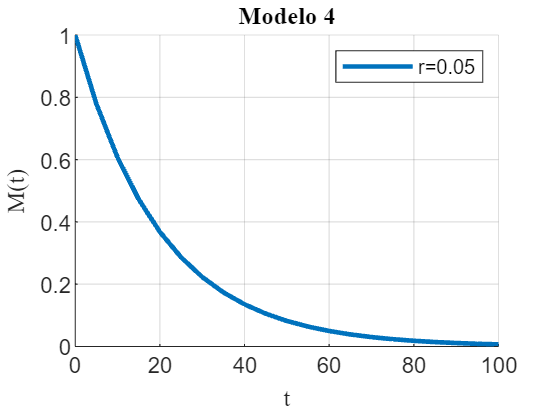

figure;
hold on;
for i = 1:1%n
    M_subs = subs(M, [r t0, M0], [r_values(i), ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['r=' num2str(r_values(i))]);
end
xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Modelo 4','FontName','latex');
legend('show');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra (para r = 0.8, los valores de M(t) son menores).

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=-r\cdot M\\
M=0
\end{array}$$


syms M r
eq =-r*M == 0;
solve(eq,M)

$$ans = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Nombre del modelo

model_name = "modelo3";

Condiciones iniciales y constantes del modelo:

k_values =  [0,0,0];
r_values = [-0.4, -0.1, -0.8];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
M1 = signals{1}.Values.Data

M1 =    -0.4000   -0.1000   -0.8000
   -0.3618   -0.0975   -0.6544
   -0.3209   -0.0946   -0.5147
   -0.2846   -0.0918   -0.4049
   -0.2524   -0.0891   -0.3185
   -0.2239   -0.0865   -0.2506
   -0.1985   -0.0839   -0.1971
   -0.1761   -0.0815   -0.1550
   -0.1562   -0.0790   -0.1220
   -0.1385   -0.0767   -0.0959


M = signals{2}.Values.Data

M =     1.0000    1.0000    1.0000
    0.9044    0.9752    0.8180
    0.8021    0.9464    0.6434
    0.7114    0.9184    0.5061
    0.6310    0.8913    0.3981
    0.5596    0.8649    0.3132
    0.4963    0.8394    0.2464
    0.4402    0.8146    0.1938
    0.3904    0.7905    0.1524
    0.3463    0.7671    0.1199


signal_time = signals{1}.Values.Time;

#### Gráfica 1

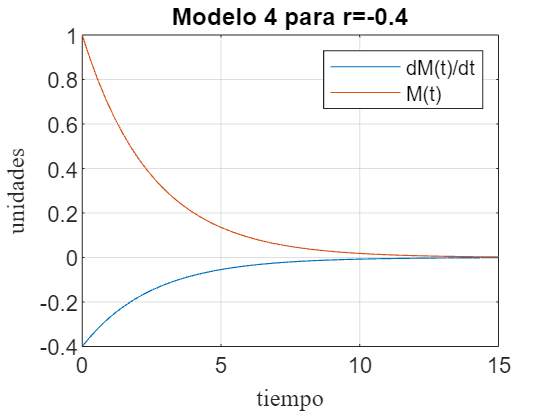

[m, n] = size(M1);
for i =1:1%n
    figure
    plot(signal_time, M1(:,i))
    hold on
    plot(signal_time, M(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 4 para r=' num2str(r_values(i))]);
    legend('dM(t)/dt','M(t)');
    hold off
end 

#### Gráfica 2

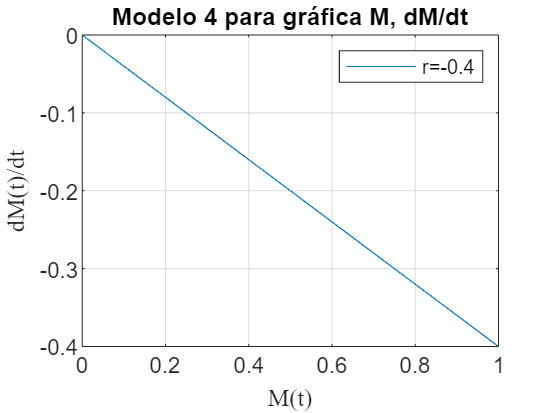

[m, n] = size(M1);
figure
for i =1:1%n
    plot(M(:,i), M1(:,i), 'DisplayName', ['r=' num2str(r_values(i))])
    grid on
    xlabel("M(t)","FontName","latex");
    ylabel("dM(t)/dt","FontName","latex");
    title('Modelo 4 para gráfica M, dM/dt');
    hold on
end 
legend('show')

## Modelo 5

Modelo de crecimiento exponencial.


$$\begin{array}{l}
\frac{\mathrm{dM}}{\mathrm{dt}}=r\cdot M\\
\mathrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms M(t) M0 t0 r

edo = diff(M, t, 1) == r*M;
cond = [M(t0)==M0];

M(t) = dsolve(edo, cond)

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t}\,{\mathrm{e}}^{-r\,t_{0}}$$

M(t) = collect(M(t), [r,t])     % para sacar factor comun

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t}\,{\mathrm{e}}^{-r\,t_{0}}$$

No hay un estado estacionario (equilibrio evidente).

El proceso es igual que el del modelo anterior con el signo negativo.

#### Tasa de duplicación: 

Tiempo que transcurre hasta que la cantidad física es el doble de la inicial.


$$M\left(t\right)=2\cdot M_o$$


tasa_dup = solve(M == 2*M0, t)

$$tasa\_dup = \frac{\log\left(2\,{\mathrm{e}}^{r\,t_{0}}\right)}{r}$$

#### 2. Sustitución de valores iniciales y constante r

r_values = [0.05, 0.1, 0.2];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(r_values);

#### 3. Gráfica para cada caso

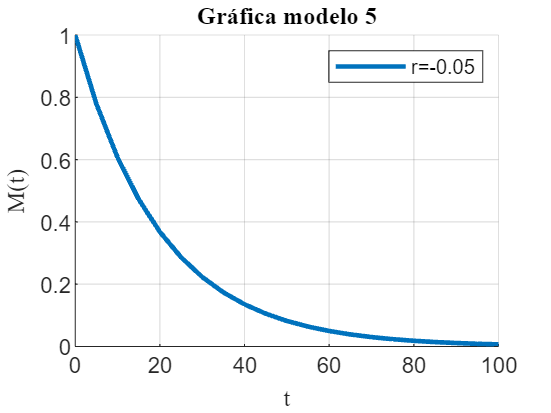

figure;
hold on;
for i = 1:1%n
    M_subs = subs(M, [r t0, M0], [r_values(i), ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['r=' num2str(r_values(i))]);
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Gráfica modelo 5','FontName','latex');
legend('show');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra (para r = 0.8, los valores de M(t) son menores).

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=r\cdot M\\
M=0
\end{array}$$


syms M r
eq =r*M == 0;
solve(eq,M)

$$ans = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Nombre del modelo

model_name = "modelo3";

Condiciones iniciales y constantes del modelo:

k_values =  [0,0,0];
r_values = [0.4, 0.1, 0.8];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data2 = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals2 = sim_data2.yout;
M1 = signals2{1}.Values.Data

M1 = 1.0e+05 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0001


M = signals2{2}.Values.Data

M = 1.0e+05 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0001


signal_time = signals2{1}.Values.Time;

#### Gráfica 1

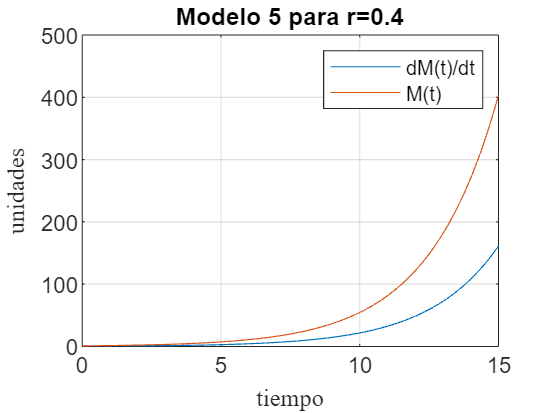

[m, n] = size(M1);
for i =1:1%n
    figure
    plot(signal_time, M1(:,i))
    hold on
    plot(signal_time, M(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 5 para r=' num2str(r_values(i))]);
    legend('dM(t)/dt','M(t)');
    hold off
end 

#### Gráfica 2

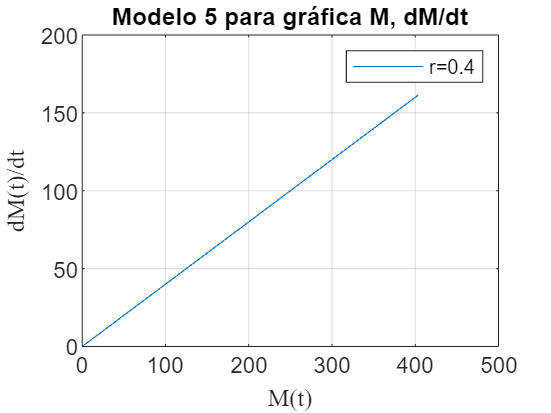

[m, n] = size(M1);
figure
for i =1:1%n
    plot(M(:,i), M1(:,i), 'DisplayName', ['r=' num2str(r_values(i))])
    grid on
    xlabel("M(t)","FontName","latex");
    ylabel("dM(t)/dt","FontName","latex");
    title('Modelo 5 para gráfica M, dM/dt');
    hold on
end 
legend('show')

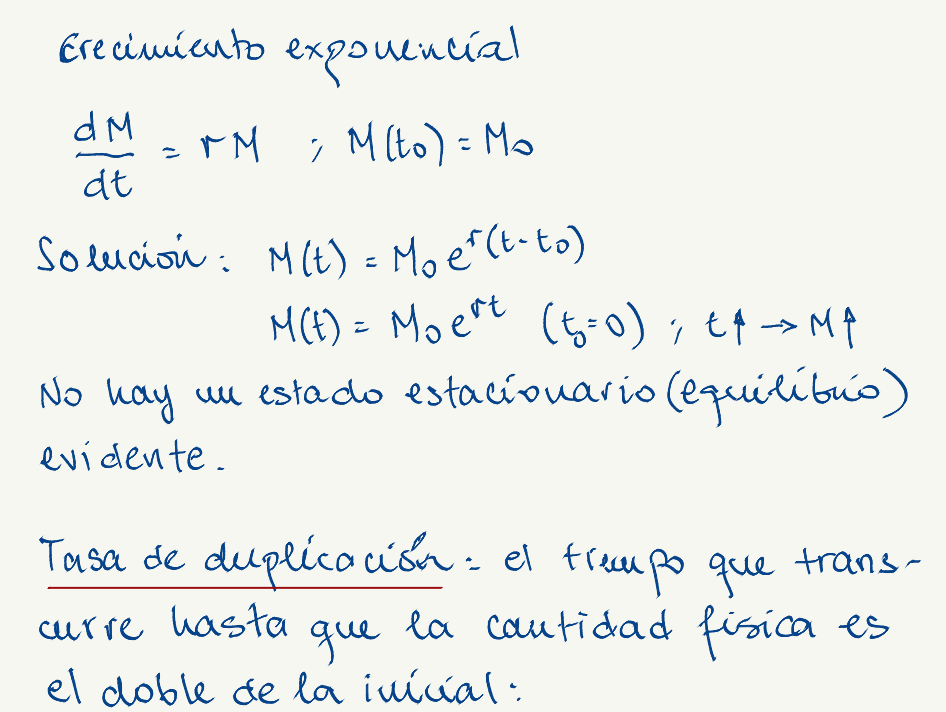

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.